# Programación Avanzada de Simulink 

# Crear una estación con dos robots independientes

# Uso de fichero **.mat* ya compilados

Dificultad: Alta (Básico)

clear all
close all


## Introducción

- Se va a crear una estación con dos robots en iconos *Subsystem *para poder ser modificados

- Si se compila la estación completa se crearía un robot con $12$ grados de libertad

- En vez de eso se va a compilar cada robot por separado e integrarlo en la estación de dos robots. Para ello se usarán ficheros **.mat* ya compilados.

- Con ello cada robot es independiente en sus movimientos

## Programación avanzada en Simulink

### Subsistemas para guardar los robots

- El subsistema va a tener una máscara, de forma que los parámetros internos del robot, $baseRobot$ y $q0\_$ no deban ser modificados en el subsistema. 

- La máscara hace que las variables internas del subsistema no se modifiquen, como si fuera una función en lenguaje de programación normal. 

- Los subsistemas de los robots se llaman con el icono de abrir subsistemas.

- Si hay varios robots en la estación, los subsistemas no deben ser modificado, solo los parámetros de la máscara de los mismos.

### Robot variable en una estación

- El robot va a ser un icono subsistema. De esa forma nuestra estación puede poner un robot definido como subsistema, por ejemplo, *Rob_irb120_Cin*. 

- Esto permite cambiar el robot y trabajar siempre con el mismo robot base.

### Modelo básico de un solo robot

- Se ha creado una estación básica para un robot variable, la pinza y la carga.

- Cuando se compile el robot a *RigidBody* se va a emplear este robot de forma que cada robot en *RigidBody* sea independiente.

- El objeto $Cin$ se ejecuta con el robot compilado independiente y dando la entrada que le corresponde dentro de las entradas Simulink.

## 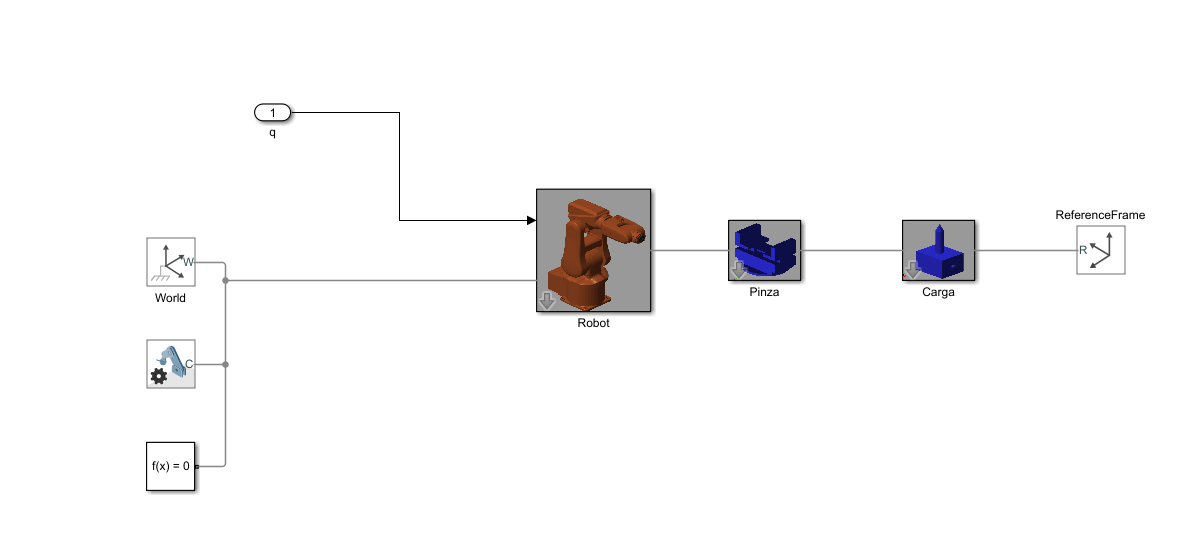

Estación con un robot variable, pinza y carga

## Obtener un modelo de un robot estándar para usarlo en un modelo con 2 robots

- Si el modelo de Simulink tiene dos robots puede ser interesante obtener el modelo de cada robot de forma independiente.

- En $Estacion1$ tenemos un modelo de un robot estándar con pinza y carga.

- Obtenemos el objeto RigidBody de ese robot y lo usamos con el objeto $Cin$ para crear el de la estación con dos robots. Debemos poner a partir de qué entrada pertenece el robot.

- Repetimos lo mismo con el otro robot.

- La simulación será de un robot en una estación de dos robots.

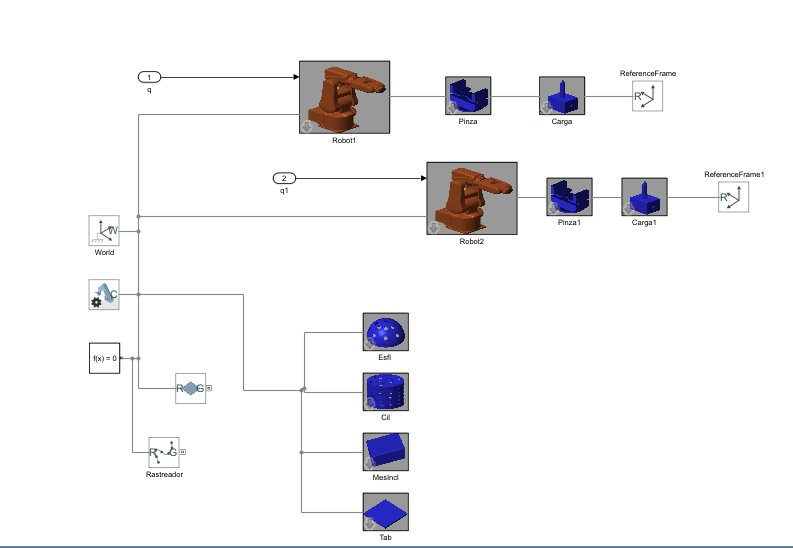

Estación con dos robots variables


clear all

deg= pi/180;

% Estación básica con 1 Robot variable

Estacion= 'C15S2_2Robots_Variables';
% Nombres de robots que se quieren poner en la estación
NomRobot1= 'ABB_irb120';
NomRobot2= 'ABB_Gofa';
%NomRobot2= '';

% Se definen los dos robots 
r1= load(NomRobot1);
r2= load(NomRobot2);


% Variables de simulink de la estación2

% Posición inicial del robot y del rastreador
% Estas variables van a ser usadas por los objetos Cin como variables del sistema 
% No deben modificarse en el programa 
% Se tienen 12 variables internas, 6 de cada robot

q0_= zeros(1,12);
pose_= randn(3,3)*1e-3;

% Esfera
Esf= Pieza('Esfera');
Esf.Base([[0,-350,0]*1e-3, [0,0,0]*deg]);
Esf.Color([0,0.3,0.8,0.7]);

% Mesa inclinada (icono constante)
MesInc= Pieza('MesaInclinada');
MesInc.Base([[0,0, 0]*1e-3, [0,0,0]*deg]);
% Ejes de la mesa por 3 puntos
% Puntos para definir los ejes de la mesa
x1= [0.4000, 0.1330, 0];
x2= [0.1500, -0.3000, 0];
y1= [0.7232, -0.0536, 0.1000];
MesInc.Tcp(Prod(x1,x2,y1));
MesInc.Color([0.3, 0.8, 0.2, 0.7]);

% Cilindro (icono constante)
Cil= Pieza('Cilindro');
Cil.Base([[0, 300, 900]*1e-3, [0, 90, 0]*deg]);
Cil.Color([0.4,0.7,0.2,0.7]);


ans = 'ABB_irb120'

% Tablero (icono constante)
Tab= Pieza('Tablero');
Tab.Base([[200, 200, 100]*1e-3, [0, 0, 30]*deg]);

ans = 'ABB_Gofa'

Tab.Color([0.2,0.5,0.1,0.7])


% Posición de la base del robot
open_system(Estacion)

Herramienta: Body10
Simulación. Ts= 0.100 m/s



% Definimos en la estación con dos robots, los robot que queremos estación el robot que queremos
% Ver el robot que hay

ans =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'Body01'  'Body02'  'Body03'  'Body04'  'Body05'  'Body06'  'Body07'  'Body08'  'Body09'  'Body10'}
      BaseName: 'Base'
       Gravity: [0 0 -9.8066]
    DataFormat: 'row'


set_param([Estacion,'/Robot1'], 'ReferencedSubsystem', NomRobot1);
get_param([Estacion,'/Robot1'], 'ReferencedSubsystem')


Herramienta: Body10
Simulación. Ts= 0.100 m/s


set_param([Estacion,'/Robot2'], 'ReferencedSubsystem', NomRobot2);
get_param([Estacion,'/Robot2'], 'ReferencedSubsystem')


ans =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'Body01'  'Body02'  'Body03'  'Body04'  'Body05'  'Body06'  'Body07'  'Body08'  'Body09'  'Body10'}
      BaseName: 'Base'
       Gravity: [0 0 -9.8066]
    DataFormat: 'row'




rob1= Cin(r1.robot, Estacion, r1.TcpCarga, r1.q0, 1);
% Cambio posición inicial de robot
r1.baseRobot= [[-200,0,0]*1e-3, [0,0,0]*deg];
rob1.Hbody(r1.baseRobot)

% El segundo robot tiene de entrada 7:12
rob2= Cin(r2.robot, Estacion, r2.TcpCarga, r2.q0, 7);
% Mover la base del robot2
r2.baseRobot= [[900,0,0]*1e-3, [180,0,0]*deg];
rob2.Hbody(r2.baseRobot)



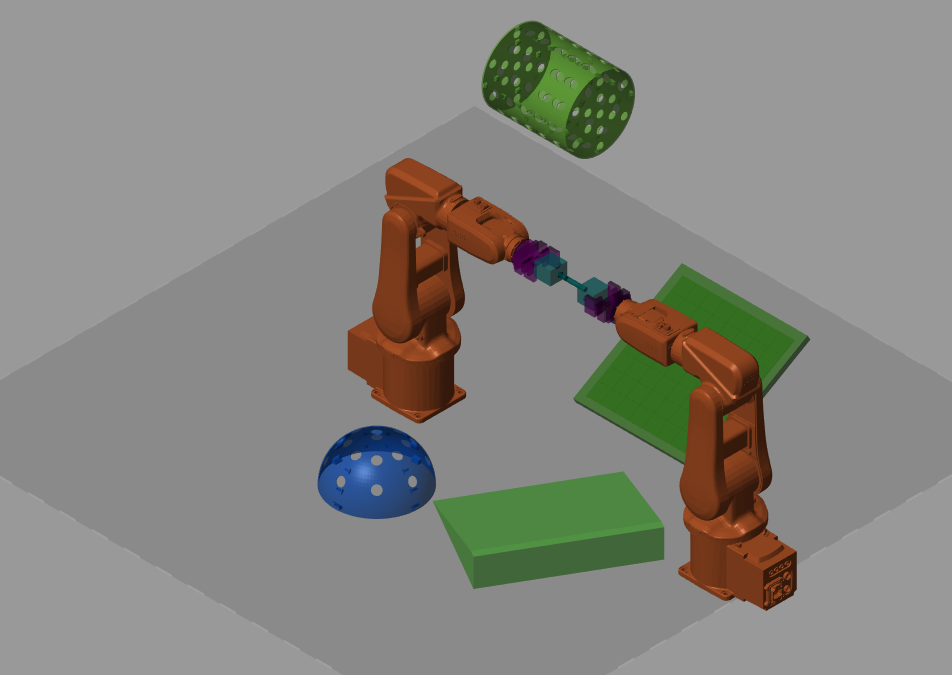

### Mover el robot modelado en la estación final

- Cada robot funciona de forma independiente.

- En la simulación de un robot, se mantiene la posición del otro robot en su estado anterior.

- Esta posición se conoce por el vector $q0\_(1:12)$ que guarda las posiciones anteriores de toda la estación.

- Cada robot modifica las suyas, el primero $q0\_(1:6)$ y el segundo $q0\_(7:12)$.


% Graba el robot 1
rob1.Rec
rob1.MoveAbsJ([0,0,0,0,0,0]);


eje= [0,0,0,0,90,0]*deg;
rob1.MoveAbsJ(eje);

punto= [[100,100,0]*1e-3,[0,0,180]*deg];
rob1.MoveJ(punto, MesInc,30);



% Graba el robot 2
rob2.Rec
rob2.MoveAbsJ([0,0,0,0,0,0]);

eje= [0,0,0,0,90,0]*deg;
rob2.MoveAbsJ(eje);
rob2.MoveJ(punto, Tab,30);



### Simulación simultánea

- Si se desea un movimiento simuláneo se debe guardar los movimientos de los dos robots de forma independiente y los posiciones si se quiere rastrear las mismas. Ambos movimientos deben tener el mismo número de puntos.

- A partir de los datos guardados se simula la planta total para esos datos

- El rastreador puede dibujar ambos movimientos, pero habrá una unión entre ellos, ya que el rastreador interpola todos los puntos que se le mandan.

% Se simula los puntos grabado
q1= rob1.save.q(:,1:6);
q2= rob2.save.q(:,7:12);
t= rob1.save.t;
q0_= zeros(1,12);

Herramienta: Body10
Simulación. Ts= 0.100 m/s


% Con rastreador
%pose_= rand(3,3)*1e-3; % Sin rastreador
pose_= [rob1.save.pose; rob2.save.pose];
sim(Estacion, t, [], [t, q1, q2]);


## Cambio de un robot por otro

- Cambiar un robot por otro se convierte en algo bastante sencillo

NomRobot2= 'Rob_UR3_DH';
set_param([Estacion,'/Robot2'], 'ReferencedSubsystem', NomRobot2)



r2= load(NomRobot2);

% El segundo robot tiene de entrada 7:12
rob2= Cin(r2.robot, Estacion, r2.TcpCarga, r2.q0, 7);

% Mover la base del robot2
r2.baseRobot= [[900,0,0]*1e-3, [180,0,0]*deg];

rob2.Hbody(r2.baseRobot);
